clear; clc; close all;

split_percent = 30/31;
split_idx = split_percent * size(features, 2);
X_Train = features(:, 1:split_idx);
Y_Train = labels(:, 1:split_idx);
X_Test = features(:, split_idx+1:end);
Y_Test = labels(:, split_idx+1:end);

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [25×3000000 double]
      Labels: [41×3000000 double]


dsTest =   MyDataStore with properties:

    Features: [25×100000 double]
      Labels: [41×100000 double]


layers = [
    featureInputLayer(N*N, "Normalization", "none")
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer((phi_max - phi_min) / delta_phi + 1)
    regressionLayer
    ]

layers =   11×1 Layer array with layers:

     1   ''   Feature Input       100 features
     2   ''   Fully Connected     150 fully connected layer
     3   ''   ReLU                ReLU
     4   ''   Fully Connected     150 fully connected layer
     5   ''   ReLU                ReLU
     6   ''   Fully Connected     150 fully connected layer
     7   ''   ReLU                ReLU
     8   ''   Fully Connected     150 fully connected layer
     9   ''   ReLU                ReLU
    10   ''   Fully Connected     41 fully connected layer
    11   ''   Regression Output   mean-squared-error

layers = [
    featureInputLayer(M*M, "Normalization", "none")
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer((phi_max - phi_min) / delta_phi + 1)
    regressionLayer
    ]

layers =   11×1 Layer array with layers:

     1   ''   Feature Input       25 features
     2   ''   Fully Connected     150 fully connected layer
     3   ''   ReLU                ReLU
     4   ''   Fully Connected     150 fully connected layer
     5   ''   ReLU                ReLU
     6   ''   Fully Connected     150 fully connected layer
     7   ''   ReLU                ReLU
     8   ''   Fully Connected     150 fully connected layer
     9   ''   ReLU                ReLU
    10   ''   Fully Connected     41 fully connected layer
    11   ''   Regression Output   mean-squared-error

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 15, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 15
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvi

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:01:03 |       115.91 |       6717.5 |          0.0010 |
|       1 |          50 |       00:01:14 |        91.54 |       4189.5 |          0.0010 |
|       1 |         100 |       00:01:14 |        83.67 |       3500.7 |          0.0010 |
|       1 |         150 |       00:01:15 |        74.99 |       2811.8 |          0.0010 |
|       1 |         200 |       00:01:16 |        73.32 |       2687.7 |          0.0010 |
|       1 |         250 |       00:01:17 |        83.38 |       3476.0 |          0.0010 |
|       1 |         300 |       00:01:17 |        71.21 |       25

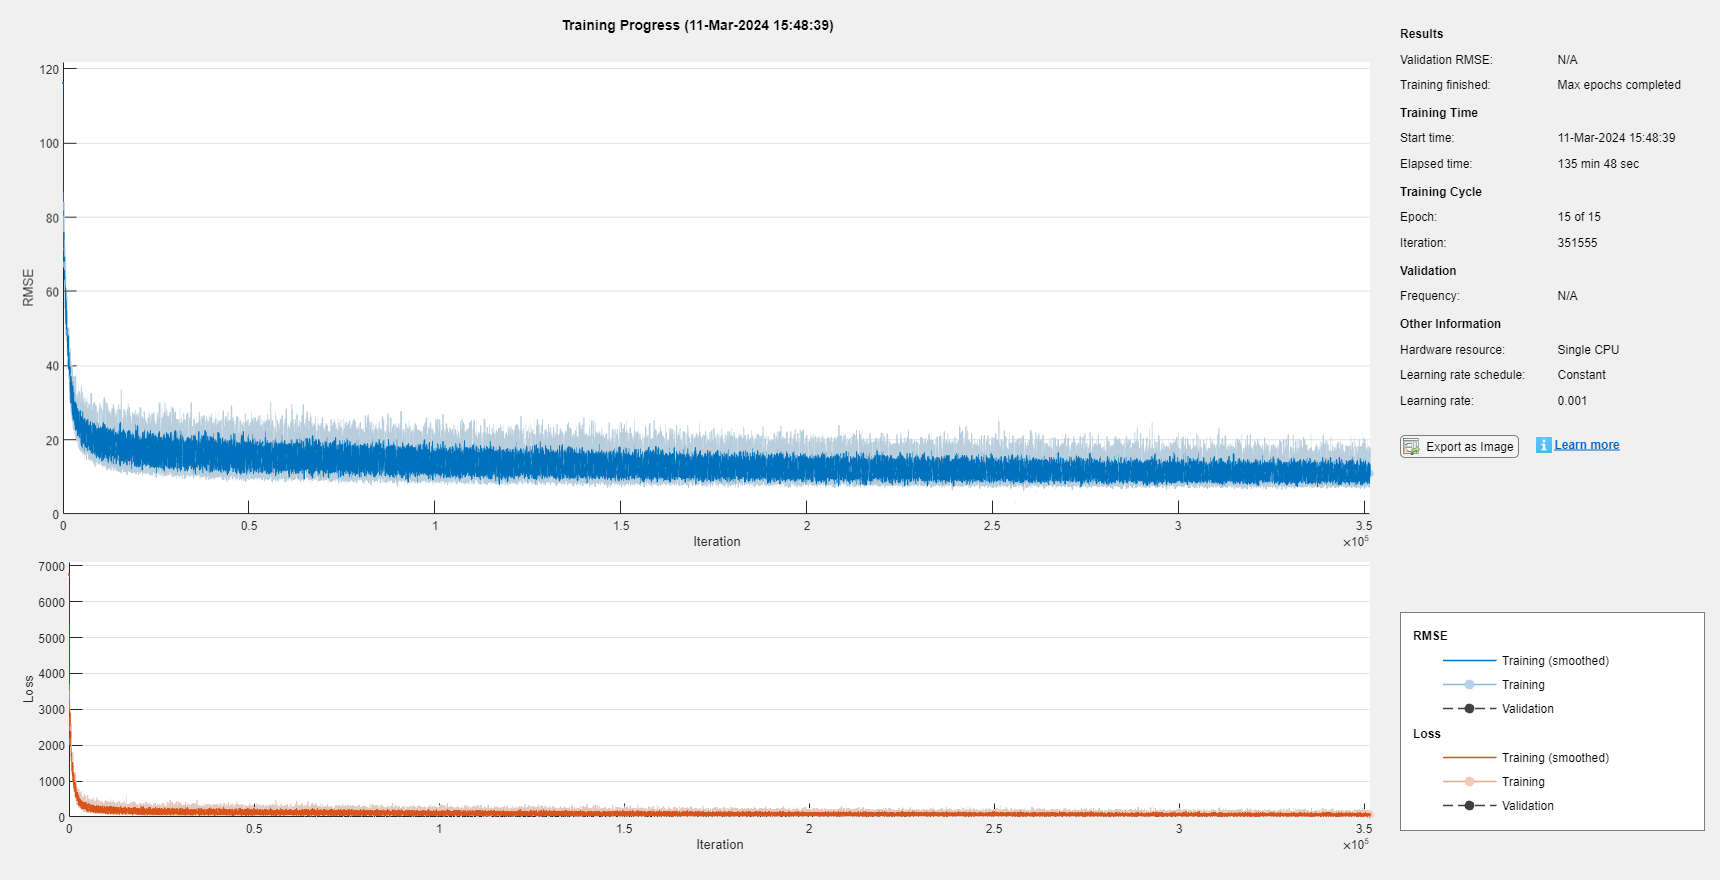

net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net = trainNetwork(dsTrain, layers, options)

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |       116.77 |       6817.2 |          0.0010 |
|       1 |          50 |       00:00:12 |       101.91 |       5192.9 |          0.0010 |
|       1 |         100 |       00:00:13 |        80.11 |       3208.8 |          0.0010 |
|       1 |         150 |       00:00:14 |        72.89 |       2656.8 |          0.0010 |
|       1 |         200 |       00:00:15 |        73.25 |       2682.6 |          0.0010 |
|       1 |         250 |       00:00:16 |        69.17 |       2392.0 |          0.0010 |
|       1 |         300 |       00:00:17 |        68.53 |       23

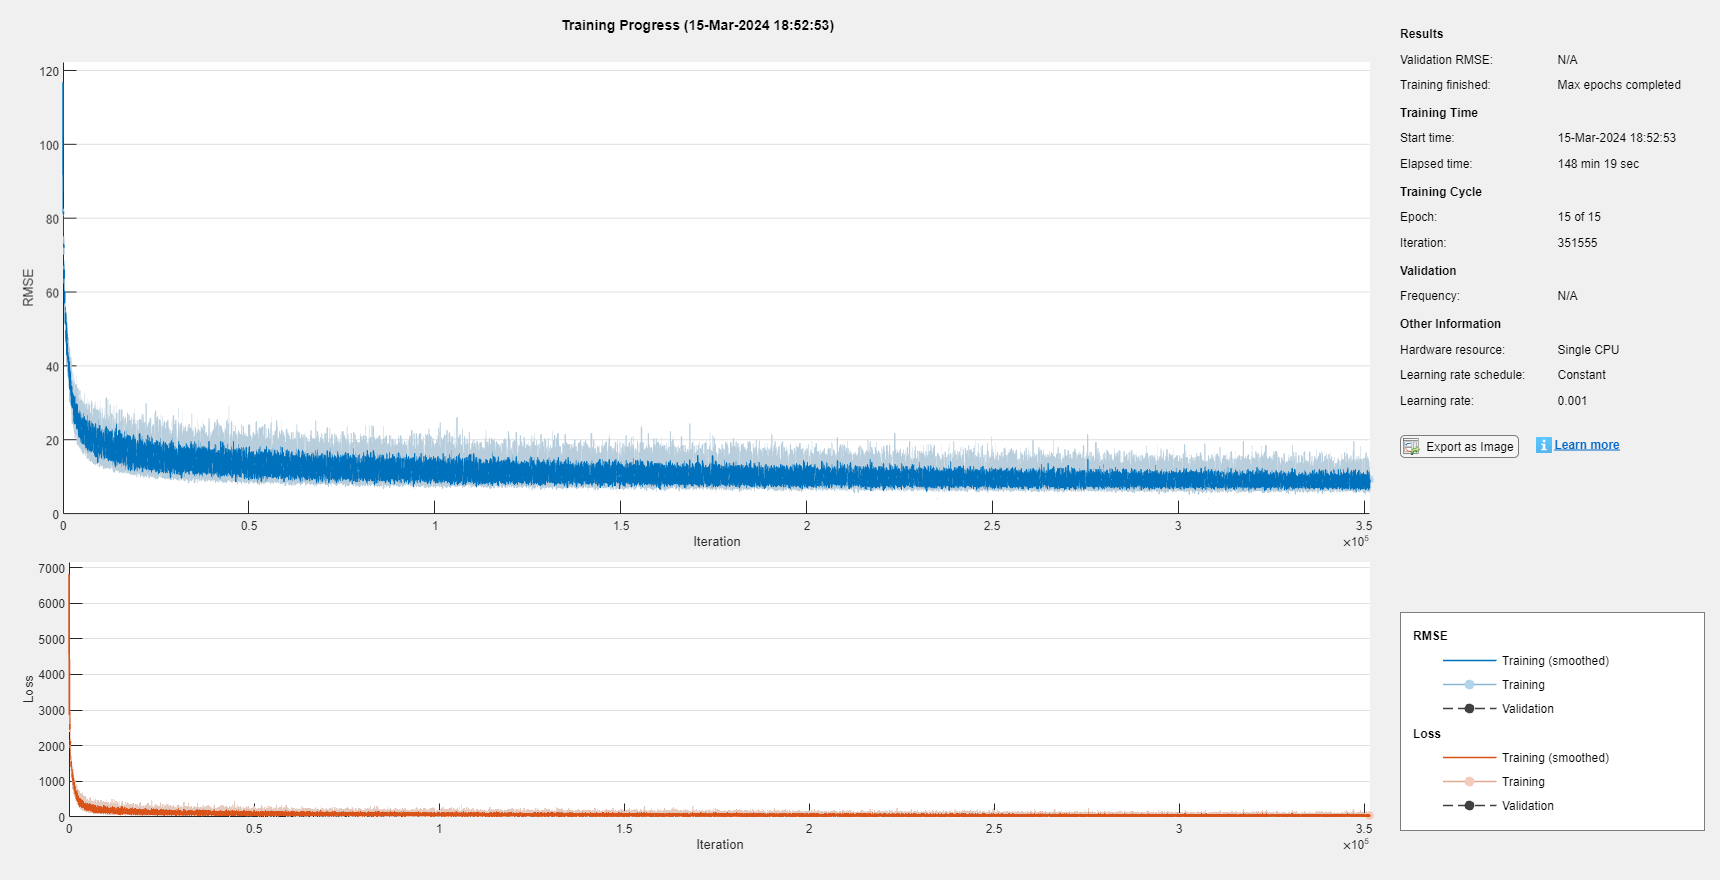

net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net = trainNetwork(dsTrain, layers, options)

YPred = predict(net, X_Test.').';
E = size(X_Test, 2);
avg_rmse = 0;
for i = 1:E
    avg_rmse = avg_rmse + rmse(YPred(:, i), Y_Test(:, i));
end
avg_rmse = avg_rmse / E

avg_rmse = single
1.2478

YPred = predict(net, X_Test.').';
E = size(X_Test, 2);
avg_rmse = 0;
for i = 1:E
    avg_rmse = avg_rmse + rmse(YPred(:, i), Y_Test(:, i));
end
avg_rmse = avg_rmse / E

avg_rmse = single
1.0057

# Testing

load Gridless_Network_2
addpath('D:\D\Alp\Master ODTÜ\Thesis\DOA\Codes\Direction-of-Arrival');
DOA = FunctionsOfDOA();

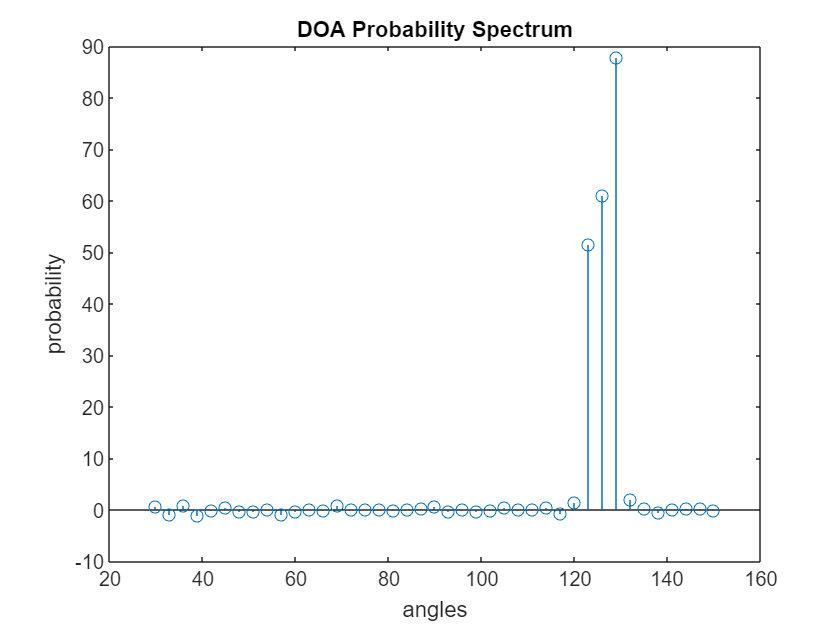

doa = 124.407 128.6891


Test(DOA, net);

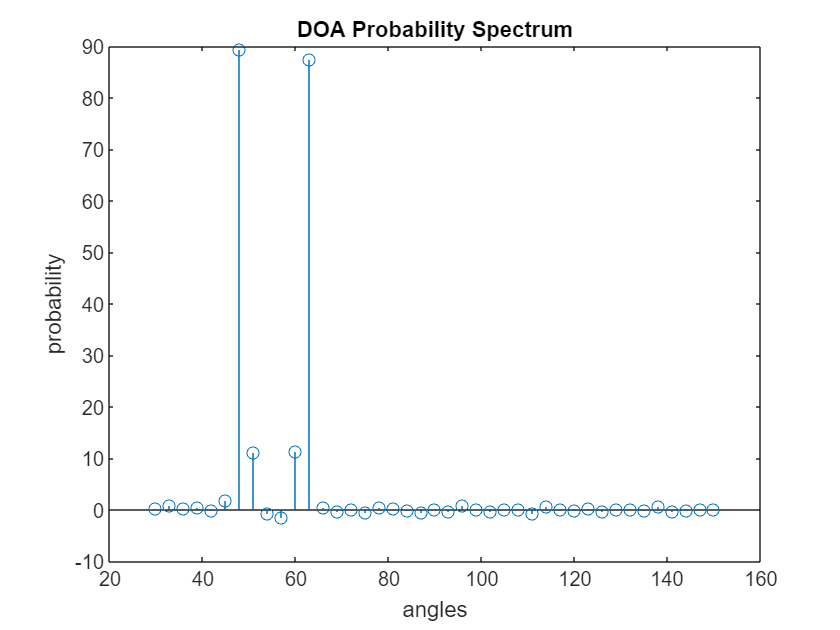

doa = 48.4841 62.6423
estimated doa = 48.3289 62.6571


Test(DOA, net);

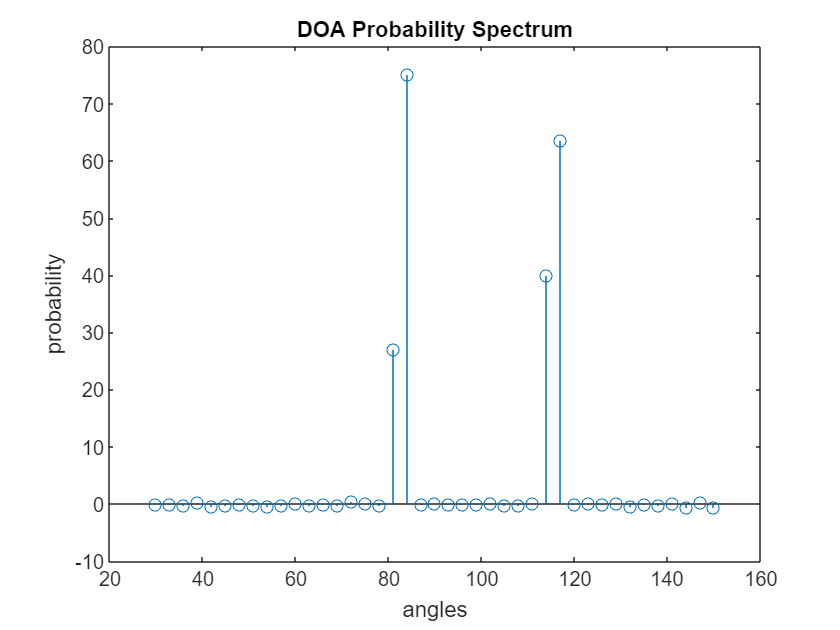

doa = 83.1684 115.9191
estimated doa = 83.2068 115.842


Test2(DOA, net);

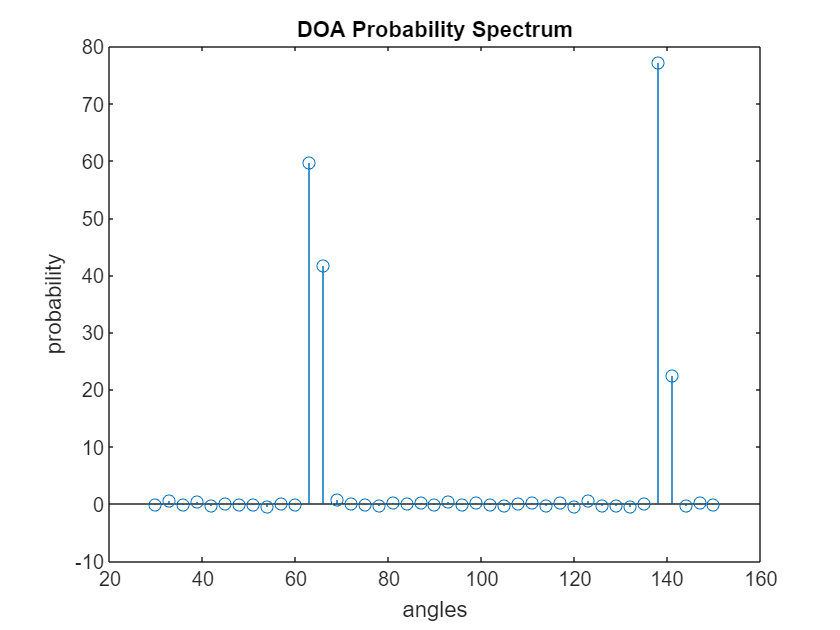

doa = 64.2236 138.6107
estimated doa = 64.2328 138.6741


Test2(DOA, net);

function r = R2r(R)
M = size(R, 1);
r = zeros(M*M, 1);

re_R = real(R);
im_R = imag(R);

r(1:M) = diag(re_R);
ind = M + 1;
for i = 2:M
    for j = 1:i-1
        r(ind:ind+1) = [re_R(i, j); im_R(i, j)];
        ind = ind + 2;
    end
end
end

function Test(DOA, net, doa_angles)
phi_min = 30;
phi_max = 150;
delta_phi = 3;
sensor_locations = [0 1 4 7 9];
M = length(sensor_locations);
N = sensor_locations(M) + 1;
L = 200;
K = 2;

if nargin == 2
   doa = (-2 * delta_phi) * ones(1, K);
   i = 1;
   while true
       temp_angle = phi_min + rand * (phi_max - phi_min);
       temp_array = abs(doa - temp_angle);
       if any(temp_array < delta_phi)
           i = i - 1;
       else
           doa(i) = temp_angle;
       end
       if i == K
           break
       end
       i = i + 1;
   end
else
    doa = doa_angles;
end
doa = sort(doa);

A = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(K, L);
SNR_dB = 15;
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;

R = (1 / L) * (y * y');
z = R(:);
z1 = DOA.Rearrange_According_to_Sensor_Locations(z, sensor_locations);
R_z1 = zeros(N);
for i = 1:N
    z1_i = z1(i:i + N - 1);
    R_z1 = R_z1 + (1 / N) * (z1_i * z1_i');
end

r_z1 = R2r(R_z1);

z = predict(net, r_z1.');

figure;
angles = phi_min:delta_phi:phi_max;
stem(angles, z);
xlabel('angles');
ylabel('probability');
title('DOA Probability Spectrum');

% for angles = phi_min:delta_phi:phi_max
% 
% end

phi_a = zeros(K, 1);
for i = 1:K
    c = floor((doa(i) - phi_min) / delta_phi);
    phi_a(i) = phi_min + c * delta_phi;
end
estimated_doa = zeros(1, K);
if phi_a(2) - phi_a(1) == delta_phi
    c = floor((doa(1) - phi_min) / delta_phi);

    d = sum(z(c+1:c+3)) / 2;

    for i = 1:K % 1:2
        phi_a = phi_min + (c + i - 1) * delta_phi;
        phi_b = phi_a + delta_phi;

        if i == 1
            a = z(c + 1);
            b = d - a;
        else % if i == 2
            b = z(c + 3);
            a = d - b;
        end

        estimated_doa(i) = (phi_a * a + phi_b * b) / (a + b);
    end
else
    for i = 1:K
        c = floor((doa(i) - phi_min) / delta_phi);

        phi_a = phi_min + c * delta_phi;
        phi_b = phi_a + delta_phi;

        a = z(c + 1);
        b = z(c + 2);

        estimated_doa(i) = (phi_a * a + phi_b * b) / (a + b);
    end
end

msg = "doa =";
for i = 1:K
    msg = msg + " " + doa(i);
end
disp(msg);

msg = "estimated doa =";
for i = 1:K
    msg = msg + " " + estimated_doa(i);
end
disp(msg);
end

function phi_star = Calculate_Phi(inp)
% inp: [phi_a phi_b a b]
K = size(inp, 1);
phi_star = zeros(K, 1);
for i = 1:K
    phi_a = inp(i, 1);
    phi_b = inp(i, 2);
    a = inp(i, 3);
    b = inp(i, 4);

    phi_star(i) = (phi_a * a + phi_b * b) / (a + b);
end
end

function Test2(DOA, net, doa_angles)
phi_min = 30;
phi_max = 150;
delta_phi = 3;
sensor_locations = [0 1 4 7 9];
M = length(sensor_locations);
N = sensor_locations(M) + 1;
L = 200;
K = 2;

if nargin == 2
   doa = (-2 * delta_phi) * ones(1, K);
   i = 1;
   while true
       temp_angle = phi_min + rand * (phi_max - phi_min);
       temp_array = abs(doa - temp_angle);
       if any(temp_array < delta_phi)
           i = i - 1;
       else
           doa(i) = temp_angle;
       end
       if i == K
           break
       end
       i = i + 1;
   end
else
    doa = doa_angles;
end
doa = sort(doa);

A = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(K, L);
SNR_dB = 5;
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;

R = (1 / L) * (y * y');

r = R2r(R);

z = predict(net, r.');

figure;
angles = phi_min:delta_phi:phi_max;
xlim([30 150]);
stem(angles, z);
xlabel('angles');
ylabel('probability');
title('DOA Probability Spectrum');

% for angles = phi_min:delta_phi:phi_max
% 
% end

phi_a = zeros(K, 1);
for i = 1:K
    c = floor((doa(i) - phi_min) / delta_phi);
    phi_a(i) = phi_min + c * delta_phi;
end
estimated_doa = zeros(1, K);
if phi_a(2) - phi_a(1) == delta_phi
    c = floor((doa(1) - phi_min) / delta_phi);

    d = sum(z(c+1:c+3)) / 2;

    for i = 1:K % 1:2
        phi_a = phi_min + (c + i - 1) * delta_phi;
        phi_b = phi_a + delta_phi;

        if i == 1
            a = z(c + 1);
            b = d - a;
        else % if i == 2
            b = z(c + 3);
            a = d - b;
        end

        estimated_doa(i) = (phi_a * a + phi_b * b) / (a + b);
    end
else
    for i = 1:K
        c = floor((doa(i) - phi_min) / delta_phi);

        phi_a = phi_min + c * delta_phi;
        phi_b = phi_a + delta_phi;

        a = z(c + 1);
        b = z(c + 2);

        estimated_doa(i) = (phi_a * a + phi_b * b) / (a + b);
    end
end

msg = "doa =";
for i = 1:K
    msg = msg + " " + doa(i);
end
disp(msg);

msg = "estimated doa =";
for i = 1:K
    msg = msg + " " + estimated_doa(i);
end
disp(msg);
end